# Ejercicio N°10

clc;
clear;

Se definen simbólicas las variables

syms t vc1(t) vc2(t) il1(t) il2(t) L1 L2 K1 K2;

Se plantean las ecuaciones y se obtienen las matrices de la forma generalizada

M=[-K1 0 0 0;0 K2 0 0;0 0 L1 L2;0 0 0 -L2]

$$M = \left(\begin{array}{cccc} -K_{1} & 0 & 0 & 0\\ 0 & K_{2} & 0 & 0\\ 0 & 0 & L_{1} & L_{2}\\ 0 & 0 & 0 & -L_{2} \end{array}\right)$$

N=[0 0 1 0; 0 0 -1 1;1 0 0 0;0 1 0 0]

N =      0     0     1     0
     0     0    -1     1
     1     0     0     0
     0     1     0     0


u=[0;0;0;0]

u =      0
     0
     0
     0


Se expresan las matrices de la forma normalizada

A=-1.*(M\N)

$$A = \left(\begin{array}{cccc} 0 & 0 & \frac{1}{K_{1}} & 0\\ 0 & 0 & \frac{1}{K_{2}} & -\frac{1}{K_{2}}\\ -\frac{1}{L_{1}} & -\frac{1}{L_{1}} & 0 & 0\\ 0 & \frac{1}{L_{2}} & 0 & 0 \end{array}\right)$$

Se definen las variables de estado

x=[vc1;vc2;il1;il2]

$$x(t) = \left(\begin{array}{c} {\mathrm{vc}}_{1}\left(t\right)\\ {\mathrm{vc}}_{2}\left(t\right)\\ {\mathrm{il}}_{1}\left(t\right)\\ {\mathrm{il}}_{2}\left(t\right) \end{array}\right)$$

Expresando el sistema en forma diferencial

odes = diff(x) == A*x

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}{\mathrm{vc}}_{1}\left(t\right)=\frac{{\mathrm{il}}_{1}\left(t\right)}{K_{1}}\\ \frac{\partial }{\partial t}{\mathrm{vc}}_{2}\left(t\right)=\frac{{\mathrm{il}}_{1}\left(t\right)}{K_{2}}-\frac{{\mathrm{il}}_{2}\left(t\right)}{K_{2}}\\ \frac{\partial }{\partial t}{\mathrm{il}}_{1}\left(t\right)=-\frac{{\mathrm{vc}}_{1}\left(t\right)}{L_{1}}-\frac{{\mathrm{vc}}_{2}\left(t\right)}{L_{1}}\\ \frac{\partial }{\partial t}{\mathrm{il}}_{2}\left(t\right)=\frac{{\mathrm{vc}}_{2}\left(t\right)}{L_{2}} \end{array}\right)$$

Reemplazando los valores de los componentes

clear K1 K2 L1 L2;
syms C1 C2 C3 C4;
K1=1/25;K2=1/72;L1=1;L2=18;
A=subs(A);

Las ecuaciones diferenciales son

odes = diff(x) == A*x;

Definiendo las condiciones iniciales y tiempo de simulacion

vc01=1;
vc02=0;
il01=0;
il02=0;
ti=0;
tf=10;
Xant=[vc01;vc02;il01;il02];
constantes=x(0)==Xant;
[il1Sol(t), il2Sol(t), vc1Sol(t), vc2Sol(t)] = dsolve(odes,constantes);

# Tensión en C1

vc1Sol

$$vc1Sol(t) = \frac{8\,\cos\left(10\,t\right)}{33}+\frac{25\,\cos\left(t\right)}{33}$$

# Tensión en C2

vc2Sol

$$vc2Sol(t) = \frac{8\,\cos\left(10\,t\right)}{11}-\frac{8\,\cos\left(t\right)}{11}$$

# Corriente en L1

il1Sol

$$il1Sol(t) = -\frac{16\,\sin\left(10\,t\right)}{165}-\frac{\sin\left(t\right)}{33}$$

# Corriente en L2

il2Sol

$$il2Sol(t) = \frac{2\,\sin\left(10\,t\right)}{495}-\frac{4\,\sin\left(t\right)}{99}$$

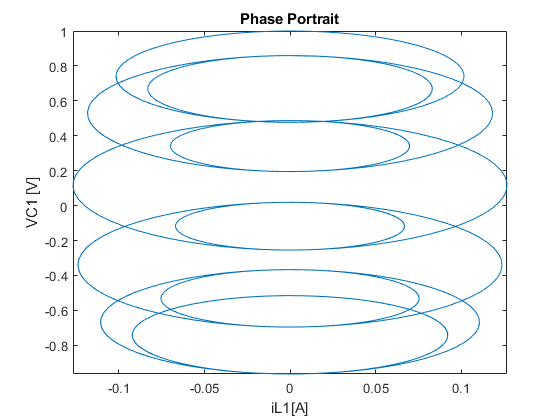

fplot(il1Sol,vc1Sol,[ti,tf])
title('Phase Portrait')
xlabel('iL1[A]')
ylabel('VC1 [V]')

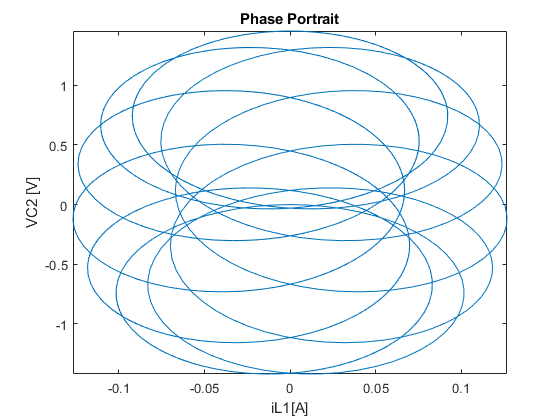

fplot(il1Sol,vc2Sol,[ti,tf])
title('Phase Portrait')
xlabel('iL1[A]')
ylabel('VC2 [V]')

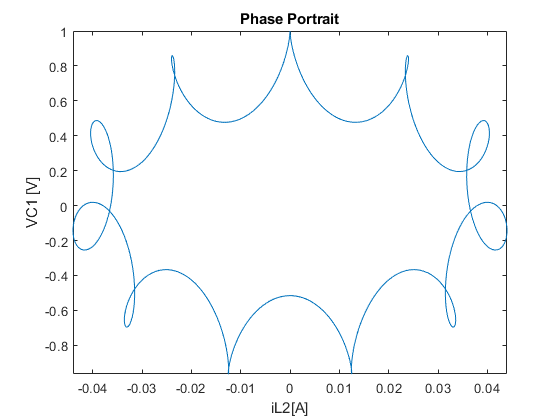

fplot(il2Sol,vc1Sol,[ti,tf])
title('Phase Portrait')
xlabel('iL2[A]')
ylabel('VC1 [V]')

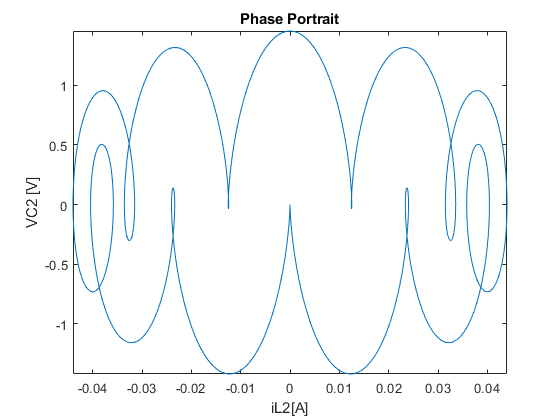

fplot(il2Sol,vc2Sol,[ti,tf])
title('Phase Portrait')
xlabel('iL2[A]')
ylabel('VC2 [V]')